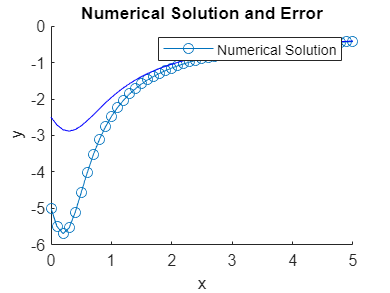

x0 = 0;
y0 = -5;
h = 0.1;
y = Euler_Explicit(@f, y0, h);

x = linspace(0, 5, length(y));
hold on
plot(x, y, '-o');
plot(x,RealFunc(x),"-b");

xlabel('x');
ylabel('y');
title('Numerical Solution and Error');
legend('Numerical Solution');

function y = Euler_Explicit(f, y0, h)
    t0 = 0;
    tp = 5;
    t = t0:h:tp;
    y = zeros(size(t));
    y(1) = y0;

    for i = 1:length(t)-1
        y(i+1) = y(i) + h * f((i+1) * h, y(i));
    end
end

function fullderi = f(x, y)
    fullderi = x.*y.^2 + 2*y;
end

function ye = RealFunc(x)
    ye = (20.*exp(2.*x))./(exp(2.*x)-10.*x.*exp(2.*x)-9);
end


